# **Stiffness matrix of rectangular QUAD finite elements**

We want to evaluate Stiffness matrix of a rectangular a x Gamma*a QUAD element

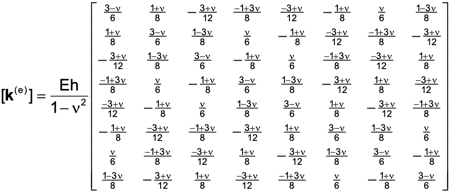

Ke(1,1)=(1/(1-nu^2) *E*h * (3-nu)/6

--> (3-nu)*4 --> A11(1)=12, B11(1)=-4 etc...

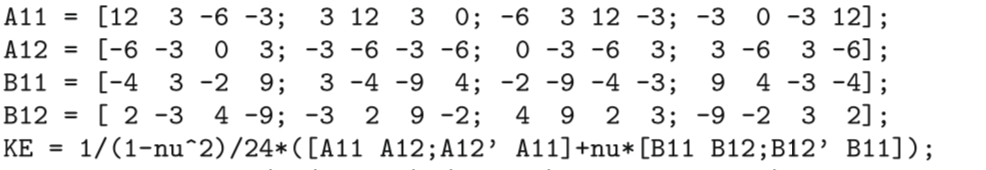

need to multiply by h in top88

## Use 2D linear elasticity

 using the Stress-strain relation for isotropic material

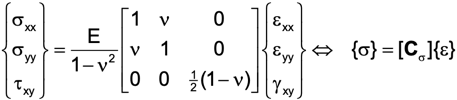

clear all; close all; 
syms E nu real
C_sigma =  ([E/(1-nu^2), E*nu/(1-nu^2), sym(0); E*nu/(1-nu^2), E/(1-nu^2), sym(0); sym(0), sym(0), 0.5*E*(1-nu)/(1-nu^2)])

$$C\_sigma = \left(\begin{array}{ccc} -\frac{\text{E}}{\nu^{2}-1} & -\frac{\text{E}\,\nu }{\nu^{2}-1} & 0\\ -\frac{\text{E}\,\nu }{\nu^{2}-1} & -\frac{\text{E}}{\nu^{2}-1} & 0\\ 0 & 0 & \frac{\text{E}\,\left(\nu -1\right)}{2\,\left(\nu^{2}-1\right)} \end{array}\right)$$

## Shape functiton for a rectangular a x gamma*a QUAD element

Shape functions for rectangular elements are product of Lagrange interpolations in the two coordinate directions. 

syms a gamma x y real

N_1=1/4 * (1 - (2 * x)/a) * (1 - (2 * y)/(a * gamma))

$$N\_1 = \left(\frac{2\,y}{a\,\gamma }-1\right)\,\left(\frac{x}{2\,a}-\frac{1}{4}\right)$$

N_2=1/4 * (1 + (2 * x)/a) * (1 - (2 * y)/(a * gamma))

$$N\_2 = -\left(\frac{2\,y}{a\,\gamma }-1\right)\,\left(\frac{x}{2\,a}+\frac{1}{4}\right)$$

N_3=1/4 * (1 + (2 * x)/a) * (1 + (2 * y)/(a * gamma))

$$N\_3 = \left(\frac{2\,y}{a\,\gamma }+1\right)\,\left(\frac{x}{2\,a}+\frac{1}{4}\right)$$

N_4=1/4 * (1 - (2 * x)/a) * (1 + (2 * y)/(a * gamma))

$$N\_4 = -\left(\frac{2\,y}{a\,\gamma }+1\right)\,\left(\frac{x}{2\,a}-\frac{1}{4}\right)$$

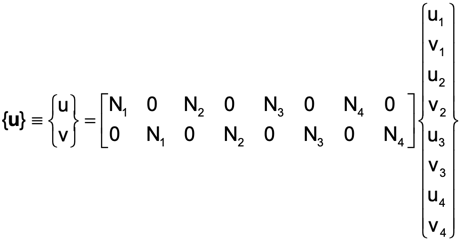

N=[N_1 sym(0) N_2 sym(0) N_3 sym(0) N_4 sym(0) ;...
   sym(0) N_1 sym(0) N_2 sym(0) N_3 sym(0) N_4]

$$N = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{3} & 0 & \sigma_{1} & 0 & \sigma_{4} & 0 & \sigma_{2} & 0\\ 0 & \sigma_{3} & 0 & \sigma_{1} & 0 & \sigma_{4} & 0 & \sigma_{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\left(\frac{2\,y}{a\,\gamma }-1\right)\,\left(\frac{x}{2\,a}+\frac{1}{4}\right)\\ \sigma_{2}=-\left(\frac{2\,y}{a\,\gamma }+1\right)\,\left(\frac{x}{2\,a}-\frac{1}{4}\right)\\ \sigma_{3}=\left(\frac{2\,y}{a\,\gamma }-1\right)\,\left(\frac{x}{2\,a}-\frac{1}{4}\right)\\ \sigma_{4}=\left(\frac{2\,y}{a\,\gamma }+1\right)\,\left(\frac{x}{2\,a}+\frac{1}{4}\right) \end{array}$$

N_check=subs(N,[a gamma], [1 1])

$$N\_check = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{3} & 0 & \sigma_{2} & 0 & \sigma_{4} & 0 & \sigma_{1} & 0\\ 0 & \sigma_{3} & 0 & \sigma_{2} & 0 & \sigma_{4} & 0 & \sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=-\left(\frac{x}{2}-\frac{1}{4}\right)\,\left(2\,y+1\right)\\ \sigma_{2}=-\left(\frac{x}{2}+\frac{1}{4}\right)\,\left(2\,y-1\right)\\ \sigma_{3}=\left(\frac{x}{2}-\frac{1}{4}\right)\,\left(2\,y-1\right)\\ \sigma_{4}=\left(\frac{x}{2}+\frac{1}{4}\right)\,\left(2\,y+1\right) \end{array}$$

Bx= [diff(N_check(1,:), x)]

$$Bx = \left(\begin{array}{cccccccc} y-\frac{1}{2} & 0 & \frac{1}{2}-y & 0 & y+\frac{1}{2} & 0 & -y-\frac{1}{2} & 0 \end{array}\right)$$

By= [diff(N_check(2,:), y)]

$$By = \left(\begin{array}{cccccccc} 0 & x-\frac{1}{2} & 0 & -x-\frac{1}{2} & 0 & x+\frac{1}{2} & 0 & \frac{1}{2}-x \end{array}\right)$$

Bxy= [diff(N_check(2,:), x)+diff(N_check(1,:), y)]

$$Bxy = \left(\begin{array}{cccccccc} x-\frac{1}{2} & y-\frac{1}{2} & -x-\frac{1}{2} & \frac{1}{2}-y & x+\frac{1}{2} & y+\frac{1}{2} & \frac{1}{2}-x & -y-\frac{1}{2} \end{array}\right)$$

The stain displacement matrix can be computed analytically using diff

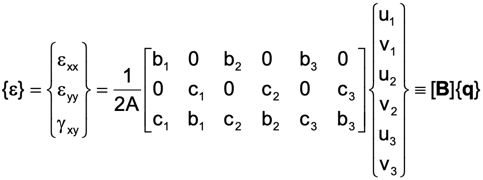

B=[diff(N_1, x), sym(0), diff(N_2, x), sym(0), diff(N_3, x), sym(0), diff(N_4, x), sym(0); ...
    sym(0), diff(N_1, y), sym(0), diff(N_2, y), sym(0), diff(N_3, y), sym(0), diff(N_4, y); ...
    diff(N_1, y), diff(N_1, x), diff(N_2, y), diff(N_2, x), diff(N_3, y), diff(N_3, x), diff(N_4, y), diff(N_4, x)]

$$B = \begin{array}{l} \left(\begin{array}{cccccccc} \sigma_{3} & 0 & -\sigma_{3} & 0 & \sigma_{4} & 0 & -\sigma_{4} & 0\\ 0 & \sigma_{1} & 0 & -\sigma_{2} & 0 & \sigma_{2} & 0 & -\sigma_{1}\\ \sigma_{1} & \sigma_{3} & -\sigma_{2} & -\sigma_{3} & \sigma_{2} & \sigma_{4} & -\sigma_{1} & -\sigma_{4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{2\,\left(\frac{x}{2\,a}-\frac{1}{4}\right)}{a\,\gamma }\\ \sigma_{2}=\frac{2\,\left(\frac{x}{2\,a}+\frac{1}{4}\right)}{a\,\gamma }\\ \sigma_{3}=\frac{\frac{2\,y}{a\,\gamma }-1}{2\,a}\\ \sigma_{4}=\frac{\frac{2\,y}{a\,\gamma }+1}{2\,a} \end{array}$$

The stiffness matrix integrand is then (h is the thickness):

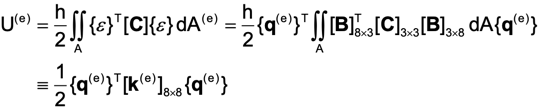

kin=B'*C_sigma*B; %to integrate twice
KE = int(int(kin, x, -(a/2), a/2), y, -((a * gamma)/2), (a * gamma)/2);

## Substitution with 1x1 quad (for topology optimization)

KE=subs(KE, [a gamma], [1 1])

$$KE = \begin{array}{l} \left(\begin{array}{cccccccc} \frac{\sigma_{3}}{\sigma_{7}} & -\sigma_{2} & \sigma_{4} & -\sigma_{1} & -\frac{\sigma_{3}}{\sigma_{6}} & \sigma_{2} & \sigma_{5} & \sigma_{1}\\ -\sigma_{2} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{1} & \sigma_{5} & \sigma_{2} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{1} & \sigma_{4}\\ \sigma_{4} & \sigma_{1} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{2} & \sigma_{5} & -\sigma_{1} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{2}\\ -\sigma_{1} & \sigma_{5} & \sigma_{2} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{1} & \sigma_{4} & -\sigma_{2} & -\frac{\sigma_{3}}{\sigma_{6}}\\ -\frac{\sigma_{3}}{\sigma_{6}} & \sigma_{2} & \sigma_{5} & \sigma_{1} & \frac{\sigma_{3}}{\sigma_{7}} & -\sigma_{2} & \sigma_{4} & -\sigma_{1}\\ \sigma_{2} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{1} & \sigma_{4} & -\sigma_{2} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{1} & \sigma_{5}\\ \sigma_{5} & -\sigma_{1} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{2} & \sigma_{4} & \sigma_{1} & \frac{\sigma_{3}}{\sigma_{7}} & \sigma_{2}\\ \sigma_{1} & \sigma_{4} & -\sigma_{2} & -\frac{\sigma_{3}}{\sigma_{6}} & -\sigma_{1} & \sigma_{5} & \sigma_{2} & \frac{\sigma_{3}}{\sigma_{7}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{\text{E}\,\left(3\,\nu -1\right)}{8\,\left(\nu^{2}-1\right)}\\ \sigma_{2}=\frac{\text{E}}{8\,\left(\nu -1\right)}\\ \sigma_{3}=\text{E}\,\left(\nu -3\right)\\ \sigma_{4}=\frac{\text{E}\,\left(\nu +3\right)}{\sigma_{6}}\\ \sigma_{5}=-\frac{\text{E}\,\nu }{\sigma_{7}}\\ \sigma_{6}=12\,\left(\nu^{2}-1\right)\\ \sigma_{7}=6\,\left(\nu^{2}-1\right) \end{array}$$

%check KE(1,1)
KE(1,1)

$$ans = \frac{\text{E}\,\left(\nu -3\right)}{6\,\left(\nu^{2}-1\right)}$$

Right ? Ke(1,1)=((3-nu)/6*(1-nu^2)) *E --> for SI UNITS please multiply by h